filename = 'sofa_hrtfs/RIEC_hrir_subject_001.sofa';
s = sofaread(filename);

% Get all zero indexed source positions
elevation = s.SourcePosition(:,2);
flat_recordings = find(elevation == 0);

% Get all the flat hrirs
% Now we got our baseline

hrir_desc = s.SourcePosition(flat_recordings,:);
hrirs = s.Numerator(flat_recordings,:,:); % [num, channel, sequence]

% Initialize a 5D array for the masked HRIRs
hrirs_masked = zeros([size(hrirs) 10]);

% Loop over each HRIR
for i = 1:size(hrirs, 1)
    % Loop over each channel
    for j = 1:size(hrirs, 2)
        % Get the current HRIR
        firFilter = squeeze(hrirs(i,j,:));
        
        % Loop over each mask
        for k = 1:10
            % Create a mask
            mask = rand(size(firFilter)) < 0.2;  % 10% of values will be masked

            % Apply the mask
            hrirs_masked_temp = firFilter;
            hrirs_masked_temp(mask) = -inf;
            
            % Store the masked HRIR in the 4D array
            % #ofHRTF, channel, HRIR, #mask
            hrirs_masked(i,j,:,k) = hrirs_masked_temp;
        end
    end
end

hrir_num = 1;
mask_num = 1;

% Get the masked HRIR
hrir_masked = squeeze(hrirs_masked(hrir_num,:,:,mask_num));

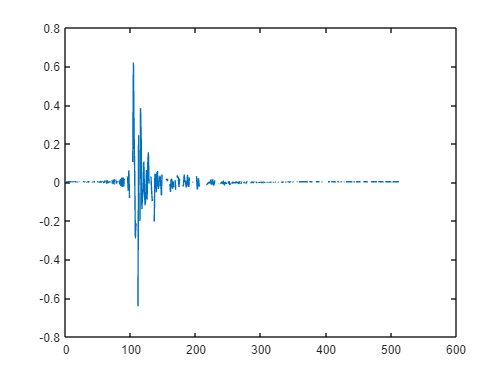

% Display the masked HRIR
%figure;
%imagesc(hrir_masked);
%colorbar;
%title(sprintf('Masked HRIR %d - Mask %d', hrir_num, mask_num));
plot(hrir_masked(1,:));

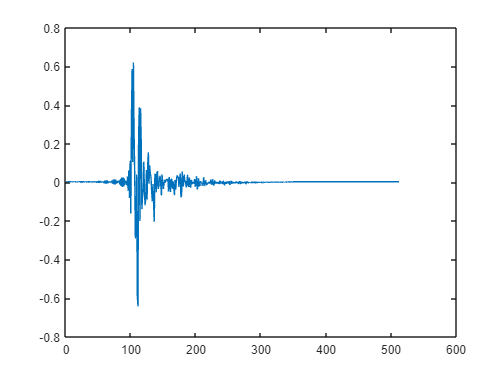

figure;
plot(squeeze(hrirs(1,1, :)));

% #ofHRTF, channel, HRIR, #mask

ans = ans(:,:,1) =

    0.0046


ans(:,:,2) =

    0.0016


ans(:,:,3) =

    0.0046


ans(:,:,4) =

    0.0025


ans(:,:,5) =

    0.0032


ans(:,:,6) =

    0.0024


ans(:,:,7) =

    0.0029


ans(:,:,8) =

    0.0025


ans(:,:,9) =

    0.0015


ans(:,:,10) =

    0.0031


ans(:,:,11) =

    0.0018


ans(:,:,12) =

    0.0037


ans(:,:,13) =

    0.0013


ans(:,:,14) =

    0.0034


ans(:,:,15) =

    0.0023


ans(:,:,16) =

    0.0027


ans(:,:,17) =

    0.0014


ans(:,:,18) =

    0.0034


ans(:,:,19) =

    0.0014


ans(:,:,20) =

    0.0038


ans(:,:,21) =

    0.0011


ans(:,:,22) =

    0.0033


ans(:,:,23) =

    0.0030


ans(:,:,24) =

   2.2790e-05


ans(:,:,25) =

    0.0051


ans(:,:,26) =

   -0.0017


ans(:,:,27) =

    0.0066


ans(:,:,28) =

  -8.2062e-04


ans(:,:,29) =

    0.0051


ans(:,:,30) =

   6.1181e-04


ans(:,:,31) =

    0.0022


ans(:,:,32) =

    0.0026


ans(:,:,33) =

  -7.5255e-05


ans(:,:,34) =

    0.0048


ans(:,:,35) =

   -0.0012


ans(:,:,36)

%